## Demo for Reddit

A lot of people on Reddit liked this script so I thought I'd use it to demonstrate 'Open in MATLAB Online'.  

Once you let it run to create the video, you'll be able to play, pause and export it to a file.

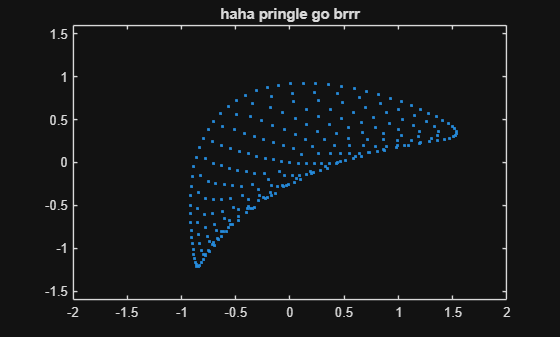

% Script from Reddit by Due_Excitement_7970
% https://www.reddit.com/r/matlab/comments/1id9g5t/made_this_for_a_class_professor_was_impressed/
% With minor modification to improve plotting speed
t = -3.14:0.025:3.14;
x = sin(pi*t);
y = 1.5*cos(pi*t);

i = 0.9;
a = 0.05;

while i > 0
    t = -3.14:a:3.14;
    x = [x,i*sin(pi*t)];
    y = [y,1.5*i*cos(pi*t)];

    i = i - 0.1;
    a = (i^-1)*.05;
end

z = 0.5*((x.^2) - (0.5*(y.^2)));
s = 0;
d = 5;
f = 5;

while s < 1000
    yrot = (y*cos(pi/270)) + (z*sin(pi/270));
    zrot = -(y*sin(pi/270)) + (z*cos(pi/270));

    y = yrot;
    z = zrot;

    xrot = (x*cos(pi/180)) - (y*sin(pi/180));
    yrot = (x*sin(pi/180)) + (y*cos(pi/180));

    x = xrot;
    y = yrot;

    xproj = x.*(f./(y+d));
    zproj = z.*(f./(y+d));
    if s==0
        h1 = plot(xproj,zproj,'.');
        xlim([-2,2])
        ylim([-1.6,1.6])
        title('haha pringle go brrr')
        hold on
    else
        set(h1,'YData',zproj,'XData',xproj);
    end

    s = s + 1;

    drawnow

end
hold off